**Curso: Profundizacion 2: Electromedicina.**

Nombre: Edwin Leandro Ramos Zambrano.

Universidad de Nariño.

**Imagenes-- Transformaciones básicas.**

Limpiar Entorno 

clc
close all
clear variables 

Importar imagen (es necesario agregar la ruta especifica de la imagen, o en su defecto ubicarla en el entorno de trabajo y quitar la ruta del comando.)

I = imread("C:\Users\elean\Documents\MATLAB\electromedicina2\imagenes\esqueleto.jpg");
I = rgb2gray(I);  % Convertir imagen a escala de gris
[mf, nc] = size(I);  % tamaño de la imagen

Declarar constantes para definir el numero de cambios sobre la distribucion de tonalidades de la imagen (tono 0-255)

lineas = 6;  % numero de diviciones de tono de gris.
inicio = 0;  %tono oscuro
fin = 255;  %tono blanco posible
c = 0;

procesamiento variables

es = round(fin/lineas);
x = zeros(lineas+1, 1);  %vector puntos en x
y = zeros(lineas+1, 1);  %vector puntos en x
m = zeros(lineas, 1);  %vector para almacenar las pendientes
b = zeros(lineas, 1);  %vector para almacenar los puntos de corte
If = zeros (mf, nc);  %matriz de imagen final
for i = inicio: es: fin
    c = c+1;
    x(c) = i;
end
x(lineas+1) = fin;
y = -x;  %vector puntos en y se puede cambiar a gusto
for i = 1: lineas
    m(i) = (y(i+1)-(y(i)))/(x(i+1)-(x(i)));
    b(i) = y(i) - x(i)* m(i);
end

Aplicacion de las variables m y b a los pixeles de la imagen segun el numero de rangos que se haya escogido en la variable "lineas"

for i = 1: mf
    for j =1: nc
        p = double(I(i, j));
        for k = 2:lineas+1
            if p > x(k-1) && p <= x(k)
                If(i, j)=m(k-1)* p +b(k-1);
            end
        end
    end
end

Graficar entrada y salida de imagen.

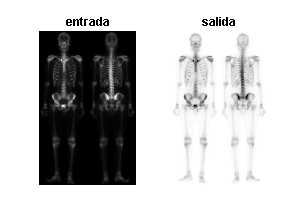

subplot(1,2,1)
imshow(I)
title("entrada");
subplot(1,2,2)
imshow(If,[])
title("salida");